clc;clear all;
load('project.mat')

Visualize the Test just for implementation ideas

testvec = []; % [test1(1:100) test2(1:100) ... test150(1:100)]
for i = 1:5
    testvec = [testvec test{1,i}(1:200)'];
end
plot(testvec)
hold on
plot(train1(1:3000));
hold on
plot(train2(1:3000));
hold on
plot(train3(1:3000));
hold on
plot(train4(1:3000));
hold on
plot(train5(1:3000));
hold off
for i = 1:200:(30000/20)
    xline(i,'--','LabelHorizontalAlignment','left','LabelOrientation','horizontal','Label',sprintf('Test %d',floor(i/200)))
end
xlim([0 1050])
xlabel('Num Sample')
ylabel('Amplitude')

Short train vectors

st1 = train1(1:5000);
st2 = train2(1:5000);
st3 = train3(1:5000);
st4 = train4(1:5000);
st5 = train5(1:5000);

Frequency Analysis     

L = size(st1,1);

fst1 = fft(st1);
P2 = abs(fst1/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

fst2 = fft(st2);
P4 = abs(fst2/L);
P3 = P4(1:L/2+1);
P3(2:end-1) = 2*P3(2:end-1);

fst3 = fft(st3);
P6 = abs(fst3/L);
P5 = P6(1:L/2+1);
P5(2:end-1) = 2*P5(2:end-1);

fst4 = fft(st4);
P8 = abs(fst4/L);
P7 = P8(1:L/2+1);
P7(2:end-1) = 2*P7(2:end-1);

fst5 = fft(st5);
P10 = abs(fst5/L);
P9 = P10(1:L/2+1);
P9(2:end-1) = 2*P9(2:end-1);

findpeaks(P1,'MinPeakHeight',0.015);
hold on
findpeaks(P3,'MinPeakHeight',0.015);
hold on
findpeaks(P5,'MinPeakHeight',0.015);
hold on
findpeaks(P7,'MinPeakHeight',0.015);
hold on
findpeaks(P9,'MinPeakHeight',0.015);
hold off
xlim([0 100])
ylim([0 0.2])
xlabel('Frequency [Hz]')
ylabel('Amplitude [V]')
title('FFT of Train Examples')
legend('Train1','Train1 Peak','Train2','Train2 Peak','Train3','Train3 Peak','Train4','Train4 Peak','Train5','Train5 Peak')

Auto-correlation analysis

x1 = xcorr(st1);
minprom = 0.0005;
mindist_xunits = 0.3;
minpkdist = floor(mindist_xunits/(1/2));
findpeaks(x1,'minpeakprominence',minprom,'minpeakdistance',minpkdist);
hold on
[val,loc] = findpeaks(x1,'minpeakprominence',minprom,'minpeakdistance',minpkdist);
[~,idx] = maxk(val,2);
plot(loc(idx),val(idx),'o','LineWidth',1.5,'MarkerSize',20)
ylabel('Auto-Correlation result')
xlabel('Sample Number')
title('Autocorrelation of Train1')
legend('Auto-correlation result')
hold off

PSD analysis

fs = 50000;
mindist_xunits = 0.3;
N = 4096;

[p, l] = pwelch(st1,rectwin(length(st1)),[],N,fs);
findpeaks(p,'npeaks',10)
hold on
[psdPeaks,locPSDpeak] = findpeaks(p,'npeaks',10);
[psdPeak,locinPSDValue] = maxk(psdPeaks,2);
plot(locPSDpeak(locinPSDValue),psdPeak,'o','LineWidth',1.5,'MarkerSize',20)
hold off
xlim([0 50])
title('PSD Estimate of Train1')

Mean Values

st1mean = mean(st1)

RMS Values

st1rms = rms(st1)

Variance Values

st1var = var(st1)

Function Test

mat = getFeatures(st1)

Make training set

featMat = [];
for i = 1:2500:300000
    featMat = [featMat;...
        getFeatures(train1(floor(i:i+5000))) 1;...
        getFeatures(train2(floor(i:i+5000))) 2;...
        getFeatures(train3(floor(i:i+5000))) 3;...
        getFeatures(train4(floor(i:i+5000))) 4;...
        getFeatures(train5(floor(i:i+5000))) 5];
end

numOfClasses = 5;

yv = (1:numOfClasses) == featMat(:,end); % try a categorical approach to check or dummyvar()
% performence
categoricalMat = [featMat(:,1:end-1) yv];

Shuffle training set

random_featMat = categoricalMat(randperm(size(categoricalMat, 1)), :);
featMat = normalize(random_featMat(:,1:end-5))';
yv = random_featMat(:,end-4:end)';

Train a model

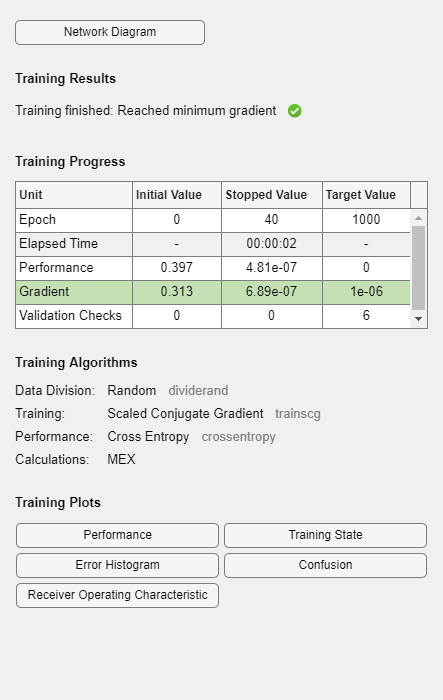

net =

    Neural Network
 
              name: 'Pattern Recognition Neural Network'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 3
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 233
        sampleTime: 1
 
    connections:
 
       biasConnect: [1; 1; 1]
      

net = patternnet([10 8]);
net = train(net,featMat,yv)

Make a small batch of the test vectors

testSet = [];
for i = 1:150
    testSet = [testSet test{1,i}(1:5000)];
end
% testSet = testSet';

Get test set features

testSetFeat = [];
for i = 1:150
    testSetFeat = [testSetFeat; getFeatures(testSet(:,i))];
end
normTestSet = testSetFeat;

Predict using the model

scores = net(normTestSet')

scores =     0.0000    0.0000    0.9945    0.0208    1.0000    0.0000    1.0000    0.0155    0.0000    0.0000    0.0000    1.0000    0.0000    0.0215    1.0000    0.0000    0.0000    0.0000    1.0000    0.0222    0.9396    0.0000    0.0000    0.0000    0.9996    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0114    0.0000    0.0000    0.0070    0.0000    0.0230    0.0000
    0.0000    1.0000    0.0000    0.0363    0.0000    0.0000    0.0000    0.0221    0.0000    0.0000    0.0000    0.0000    1.0000    0.0377    0.0000    0.0000    0.0000    0.0000    0.0000    0.0314    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0232    0.0000    0.0000    0.0113    1.0000    0.0390

[~, maxidx] = max(scores)

maxidx =      5     2     1     3     1     5     1     3     4     5     5     1     2     3     1     5     4     3     1     3     1     2     5     4     1     4     3     3     1     4     5     4     5     5     4     3     4     1     2     3     5     1     4     3     3     4     3     2     3     4


sum(maxidx == 1)

ans = 30

sum(maxidx == 2)

ans = 30

sum(maxidx == 3)

ans = 30

sum(maxidx == 4)

ans = 30

sum(maxidx == 5)

ans = 30

nati_shait'

ans =      5     2     1     3     1     5     1     3     4     5     5     1     2     3     1     5     4     3     1     3     1     2     5     4     1     4     3     3     1     4     5     4     5     5     4     3     4     1     2     3     5     1     4     3     3     4     3     2     3     4


sum(maxidx-nati_vec')

ans = 0